%% Gs=(30+N)/(s*(0.1*s+1)*(s+20));
%Zeta>0.5 Wn>10
clc
clear
close all
N=4;
s=tf('s');
Gs=(30+N)/(s*(0.1*s+1)*(s+20))

Gs =
 
            34
  ----------------------
  0.1 s^3 + 3 s^2 + 20 s
 
Continuous-time transfer function.



ProcentajeCriterioTs=0.02;
CriterioRiso=[0.10 0.90];
ParametroSys(Gs,ProcentajeCriterioTs,CriterioRiso) %el sistema es inestable en LO no se analiza mas nada

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
  0.00e+00    -1.00e+00       0.00e+00              Inf    
 -1.00e+01     1.00e+00       1.00e+01         1.00e-01    
 -2.00e+01     1.00e+00       2.00e+01         5.00e-02    


Resultados =     '
     Ts(2.00)=NaN
     Tr=NaN
     Mp=NaN
     Tp=Inf
     Tao=NaN
     ValorF=Inf
     '


ans = NaN

% figure(1)
% step(Gs)
% figure(2)
% subplot(221),rlocus(Gs)
% subplot(223),nyquist(Gs)
% subplot(122),margin(Gs)
%% Calcular polos deseados y posicion
clc
Zeta=0.7; Wn=11; %zeta y Wn deseados
Sigma=Wn*Zeta

Sigma = 7.7000

Wd=Wn*sqrt(1-Zeta^2)

Wd = 7.8556

rlocus(Gs),sgrid(Zeta,0)
[Phi,C]=LeadLGR(Gs,Sigma,Wd,0)

Se requiere un aporte mayor a 60°, es recomendable usar 2 compensadores en adelanto


Phi = 60.6726

C =
 
  6.3846 (s+6.659)
  ----------------
     (s+18.17)
 
Continuous-time zero/pole/gain model.



%rlocus(Gs)
%% 
clc
close all
GsC=C*Gs;
Tc=feedback(GsC,1); %sistema controlado
Tk=feedback(Gs,1);
Su=feedback(C,Gs); %señal de control
ParametroSys(Tc,ProcentajeCriterioTs,CriterioRiso)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -4.18e+00                 1.00e+00       4.18e+00         2.39e-01    
 -7.70e+00 + 7.86e+00i     7.00e-01       1.10e+01         1.30e-01    
 -7.70e+00 - 7.86e+00i     7.00e-01       1.10e+01         1.30e-01    
 -2.86e+01                 1.00e+00       2.86e+01         3.50e-02    


Resultados =     '
     Ts(2.00)=0.8651
     Tr=0.3503
     Mp=0.0000
     Tp=1.5107
     Tao=0.1881
     ValorF=1.0000
     '


ans = 0.8651

ErroEpEvEa(GsC)

ans = 0

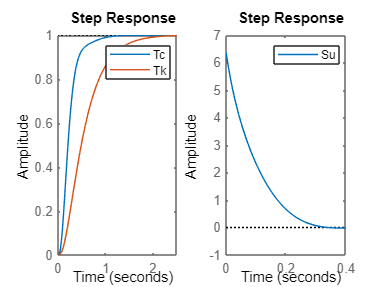

figure(2)
subplot(121),step(Tc,Tk),legend
subplot(122),step(Su),legend

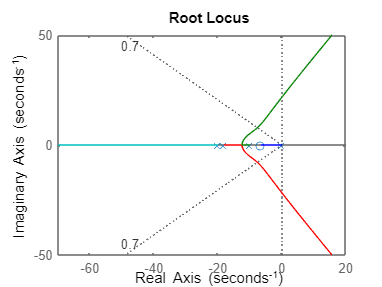

figure(3)
rlocus(GsC),sgrid(Zeta,0)